# Ajuste de datos

close all
clear
clc

Carga de datos

data=load('Mapeo_temp100621.txt');
t=data(:,1);
T_amb=data(:,72); % Temperatura ambiente
I_amb=data(:,75); %Irradiancia
HR_amb=data(:,65); %Humedad relativa ambiente

Localización de tiempo de inicio y fin de prueba

ini_prueba=8;
fin_prueba=20;
t_max=length(t);



for i=1:t_max 
    
    if t(i)<=ini_prueba
        t_ini=i;
    end
    if t(i)<=fin_prueba
        t_fin=i;
    end
end
t=t(t_ini:t_fin)-8;
zpI=polyfit(t,I_amb(t_ini:t_fin),4)

zpI =     0.5125  -12.0790   66.4485   44.4091  146.7760


I2=polyval(zpI,t);   
R2I= 1-var(I_amb(t_ini:t_fin)-I2)/var(I_amb(t_ini:t_fin))

R2I = 0.9614


zpT=polyfit(t,T_amb(t_ini:t_fin),4)

zpT =     0.0010   -0.0304    0.2914   -0.2138   23.9443


T2=polyval(zpT,t);   
R2T= 1-var(T_amb(t_ini:t_fin)-T2)/var(T_amb(t_ini:t_fin))

R2T = 0.9903


zpHR=polyfit(t,HR_amb(t_ini:t_fin),4)

zpHR =    -0.0019    0.1245   -1.3295   -1.9212   87.5956


HR2=polyval(zpHR,t);   
R2HR= 1-var(HR_amb(t_ini:t_fin)-HR2)/var(HR_amb(t_ini:t_fin))

R2HR = 0.9908


pI=trapz(t,I_amb(t_ini:t_fin))/t(length(t))

pI = 510.7147

pT=trapz(t,T_amb(t_ini:t_fin))/t(length(t))

pT = 27.5414

pHR=trapz(t,HR_amb(t_ini:t_fin))/t(length(t))

pHR = 58.0062

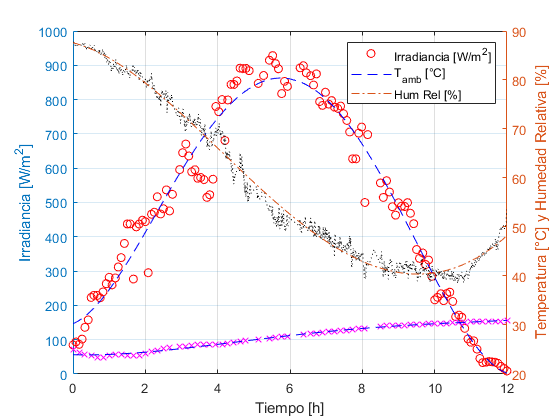


ts=length(t);

figure (1)
yyaxis left
plot(t,I_amb(t_ini:t_fin),'r o',t,I2,'b','MarkerIndices',1:10:ts);grid on
xlabel('Tiempo [h]');ylabel('Irradiancia [W/m^2]')

yyaxis right
plot(t,T_amb(t_ini:t_fin),'m x',t,T2,'b',t,HR_amb(t_ini:t_fin),'k',t,HR2,'MarkerIndices',1:20:ts);grid on
ylabel('Temperatura [°C] y Humedad Relativa [%]')
legend('Irradiancia [W/m^2]','','','T_a_m_b [°C]','','Hum Rel [%]')